# BE1 - Méthodes numériques pour les EDP

MESSINA Valentin et MUNOZ Eloi

## Partie 1 : Equation elliptique en dimension 1

**Question 1 :** Résolution 

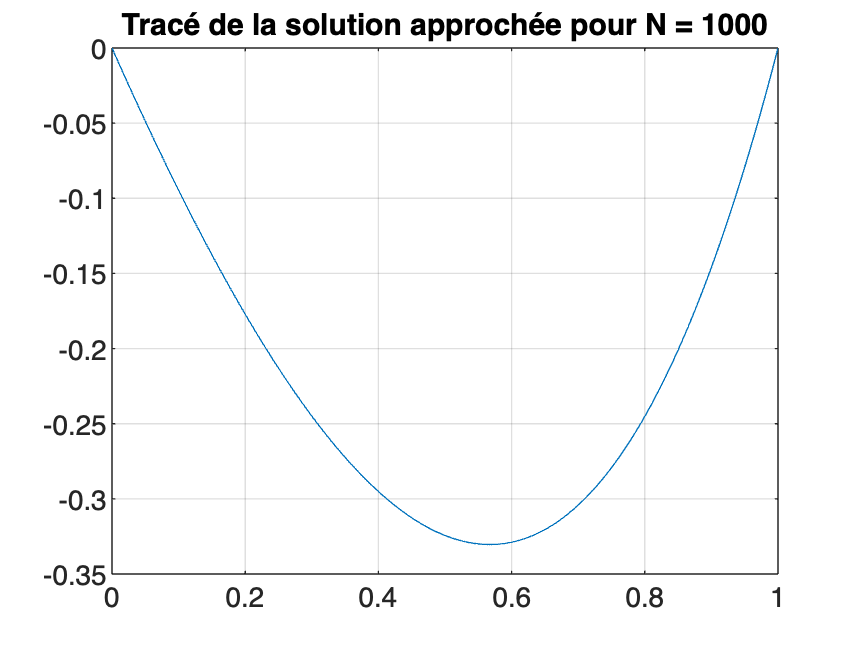

N=1000;
DeltaX = 1/(N+1);
A = mat_dir(N);
B = vect_dir(N);
U = A\B;

%Ajout des conditions aux limites
Ucond = [0 U' 0]';
X = (0:DeltaX:1)';

%Tracé de la solution
plot(X,Ucond)
grid on
title(['Tracé de la solution approchée pour N = ' num2str(N)])

**Question 2 :** Ordre de convergence 

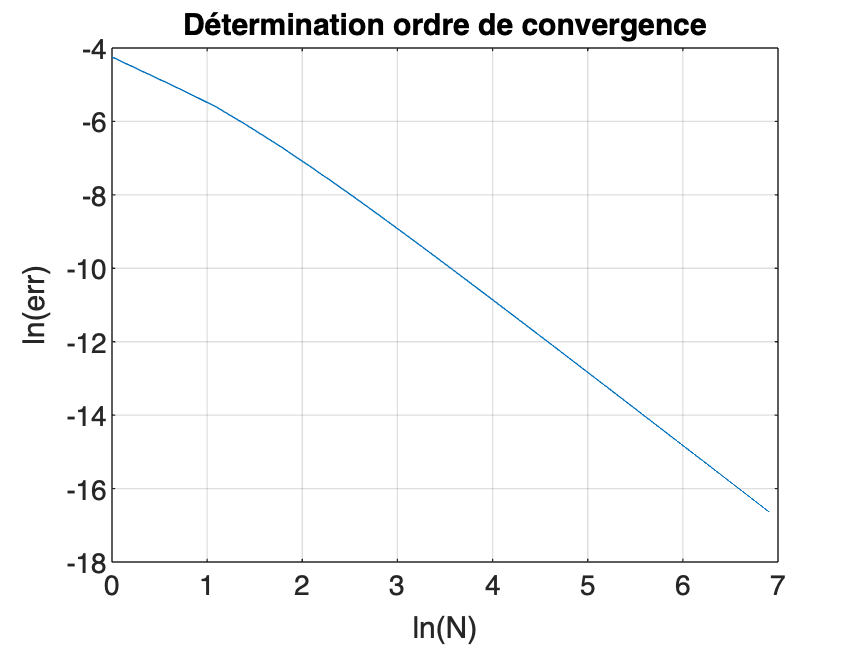

err = [1:1:N];
for n=1:N
    % Calcul de la solution exacte
    X = (0:1/(n+1):1)';
    Uex = (X-1).*(exp(X)-1);

    % Calcul de la solution approchee
    A = mat_dir(n);
    B = vect_dir(n);
    U = A\B;
    Ucond = [0 U' 0]';

    % Calcul de l'erreur
    err(n) = max(abs(Uex-Ucond));
end

% On trace pour intuiter

% plot([1:1:N], err)
% grid on
% title(['Ordre de convergence ?'])
% xlabel('N')
% ylabel('Erreur')

% Pour mq err = O(1/N^ordre), on trace :
% ln(err) en fonction de ln(N)
plot(log([1:1:N]), log(err))
grid on
title(['Détermination ordre de convergence'])
xlabel('ln(N)')
ylabel('ln(err)')


%L'odre est le coeff directeur
p = polyfit(log([1:1:N]), log(err),1) ;
ordre = -p(1)

ordre = 1.9629

## Partie 2 : Schémas pour l’équation de la chaleur en dimension 1

**Question 5 :** Résolution 

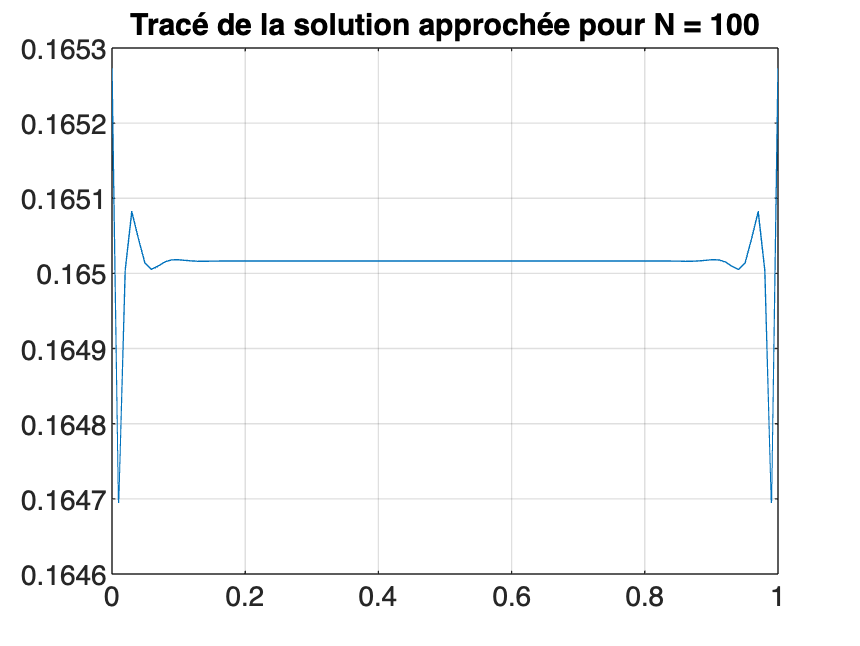

N=100;
DeltaX = 1/(N+1);
DeltaT = 0.01;
theta = 0.5;
X = [0:DeltaX:1]';
L = lap_neu(N);
A = 1/DeltaT*eye(N+2)+theta/(DeltaX^2)*lap_neu(N);
B = 1/DeltaT*eye(N+2)-(1-theta)/(DeltaX^2)*lap_neu(N);
U = X.*(1-X);
for i=1:N+1
    U=A\B*U;
end

%tracé
plot(X,U)
grid on
title(['Tracé de la solution approchée pour N = ' num2str(N)])

**Question 6 :**

Tracé solution approchée :

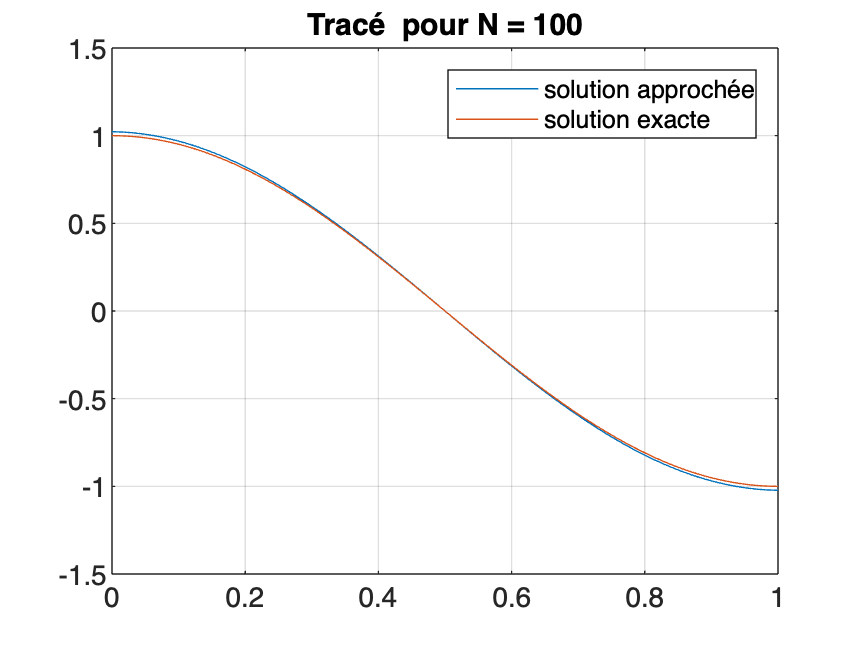

N=100;
DeltaX = 1/(N+1);
X = [0:DeltaX:1]';
A = (1/DeltaX^2)*lap_neu(N) + eye(N+2);
B = (1+pi^2)*cos(pi*X);
U = A\B;
Uex = cos(pi*X);
%tracé
plot(X,U,X,Uex)
legend('solution approchée','solution exacte')
grid on
title(['Tracé  pour N = ' num2str(N)])

On cherche l'ordre de convergence du schéma :

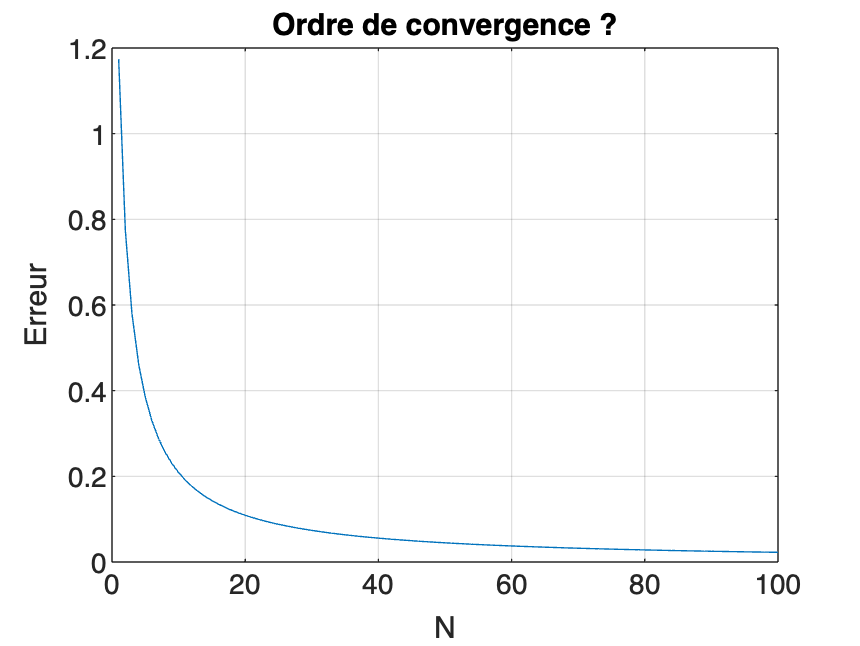

err = [1:1:N];
for n=1:N
    DeltaX = 1/(n+1);
    % Calcul de la solution exacte
    X = (0:1/(n+1):1)';
    Uex = cos(pi*X);

    % Calcul de la solution approchee
    X = [0:DeltaX:1]';
    A = (1/DeltaX^2)*lap_neu(n) + eye(n+2);
    B = (1+pi^2)*cos(pi*X);
    U = A\B;

    % Calcul de l'erreur
    err(n) = max(abs(Uex-U));
end

% On trace pour intuiter

plot([1:1:N], err)
grid on
title(['Ordre de convergence ?'])
xlabel('N')
ylabel('Erreur')

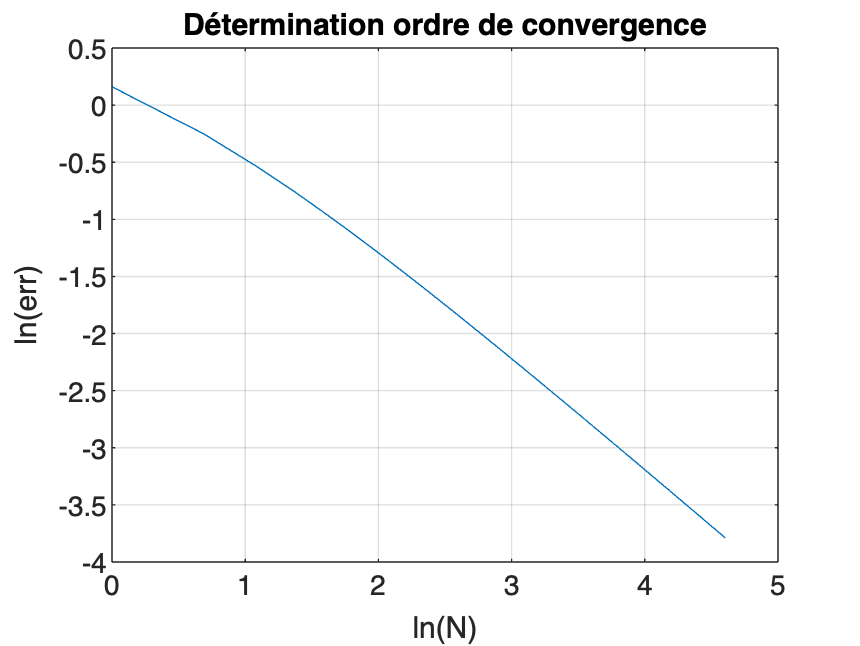


% Pour mq err = O(1/N) = O(Delta t), on trace :
% ln(err) en fonction de ln(N)
plot(log([1:1:N]), log(err))
grid on
title(['Détermination ordre de convergence'])
xlabel('ln(N)')
ylabel('ln(err)')


%L'odre est le coeff directeur
p2 = polyfit(log([1:1:N]), log(err),1) ;
ordre = -p2(1)

ordre = 0.9265

**Question 7 :**

On teste une amélioration de la prise en compte des conditions de Neumann pour retrouver un ordre 2 ce qui se traduit par un changement de la matrice qui deviennt lap_neu2 et du vecteur $B$ des conditions aux limites.

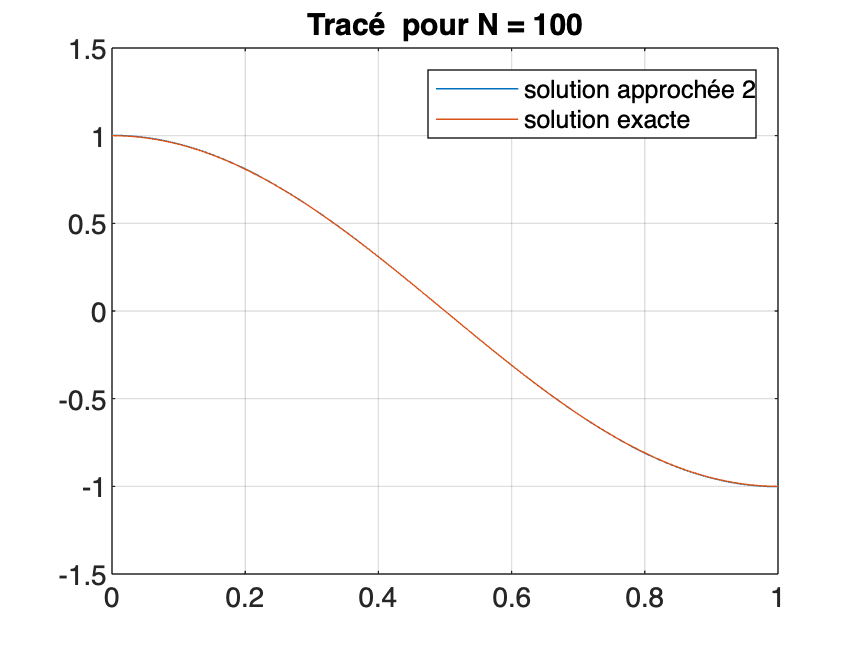

N=100;
DeltaX = 1/(N+1);
X = [0:DeltaX:1]';
A = (1/DeltaX^2)*lap_neu2(N) + eye(N+2);
B = (1+pi^2)*cos(pi*X);
B(1) = -1;
B(N+2) = 1;
U2 = A\B;
Uex = cos(pi*X);
%tracé
plot(X,U2,X,Uex)
legend('solution approchée 2','solution exacte')
grid on
title(['Tracé  pour N = ' num2str(N)])

On cherche l'ordre de convergence :

err = [1:1:N];
for n=1:N
    DeltaX = 1/(n+1);
    % Calcul de la solution exacte
    X = (0:DeltaX:1)';
    Uex = cos(pi*X);

    % Calcul de la solution approchee
    X = [0:DeltaX:1]';
    A = (1/DeltaX^2)*lap_neu2(n) + eye(n+2);
    B = (1+pi^2)*cos(pi*X);
    B(1) = -1;
    B(n+2) = 1;
    U = A\B;

    % Calcul de l'erreur
    err(n) = max(abs(Uex-U));
end

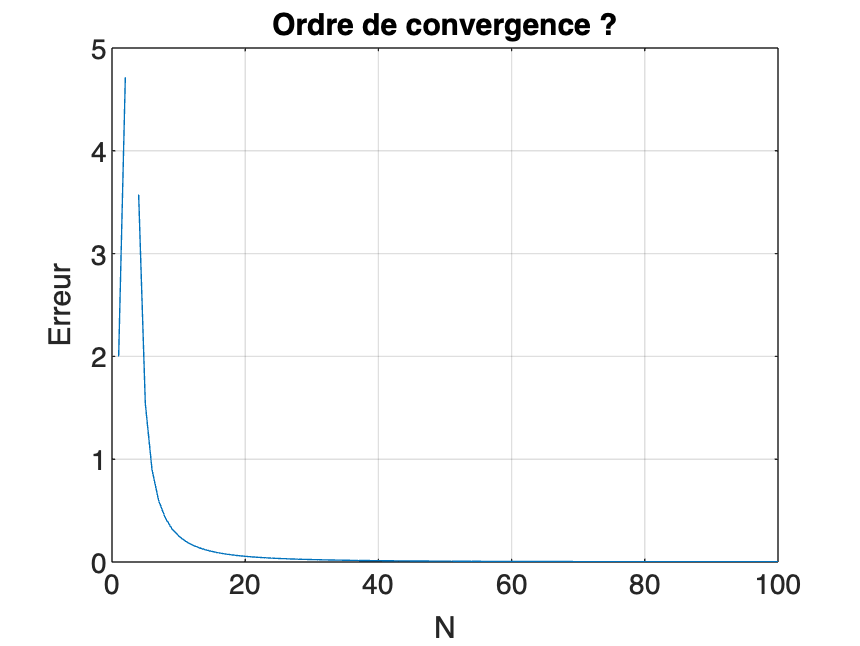


% On trace pour intuiter

plot([1:1:N], err)
grid on
title(['Ordre de convergence ?'])
xlabel('N')
ylabel('Erreur')

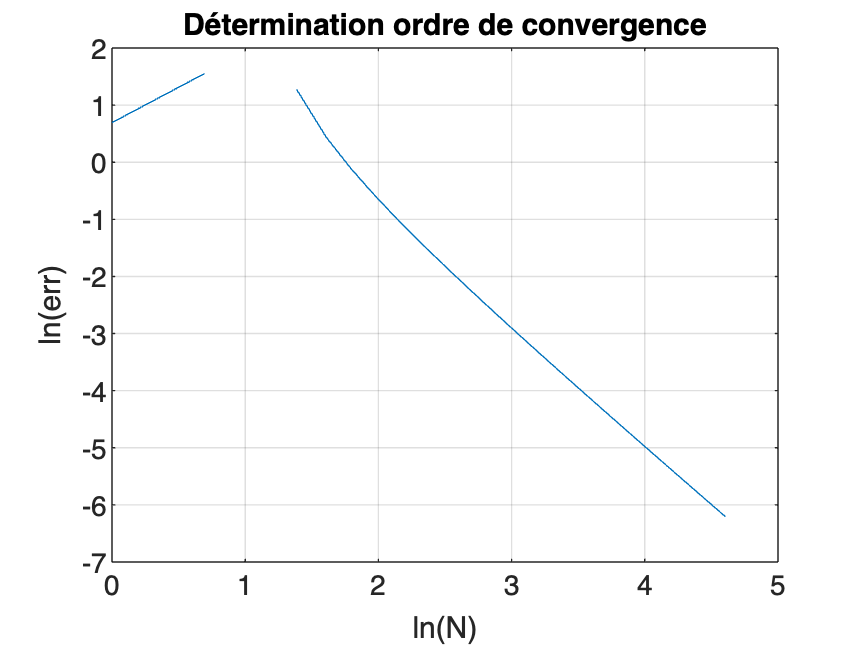

% Pour mq err = O(1/N) = O(Delta t), on trace :
% ln(err) en fonction de ln(N)
plot(log([1:1:N]), log(err))
grid on
title(['Détermination ordre de convergence'])
xlabel('ln(N)')
ylabel('ln(err)')



%L'ordre est le coeff directeur de la droite (il faut enlever la 
% portion de gauche- pour ln(N) >= 1.5, par exemple :

E = log(err);
p2 = polyfit(log([10:1:N]), E(:,10:N), 1);
ordre = -p2(1)

ordre = 2.0738

On retrouve bien un ordre 2 avec ce changement de prise en compte des conditions de Neumann. 

## Partie 3 : Décentrement pour l'équation de transport linéaire en dimension 1

**Question 8 :**

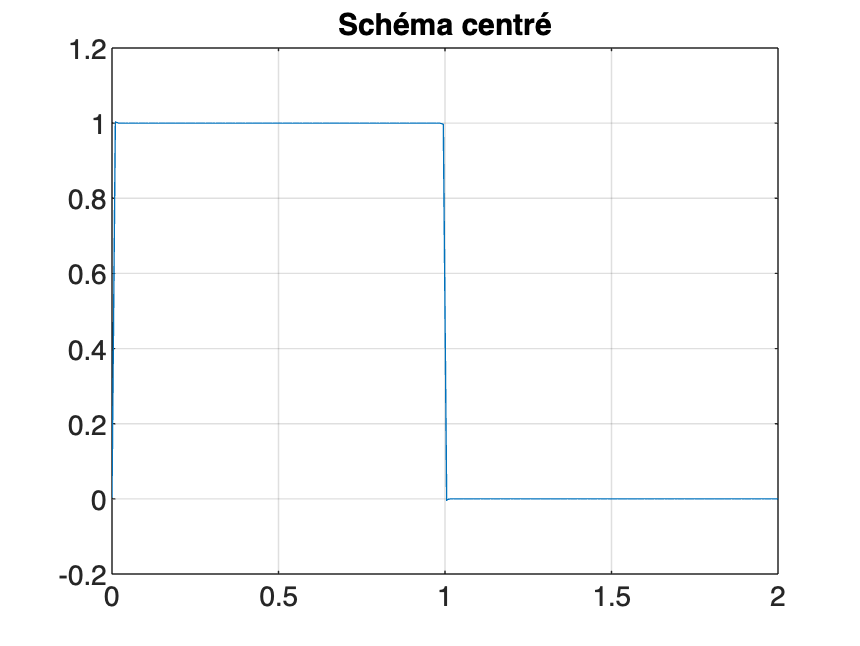

%%
Lim=2;
% Definition du domaine
deltax=0.01;
deltat=0.001;  
Z=600;
M=Lim/deltax;
N=M;
X=linspace(0,Lim,M);  % Vecteur des ordonnées 
alpha=8*pi;
% Definition des matrices de discrétisation
O=ones(1,N-1);
A1=diag(-1*O,1);
A2=diag(-1*O,-1);
Acentre=-A1+A2;
Agauche=-A1-eye(N);
Adroite=eye(N)+A2;
Ucentre=((X<1).*(X>0))';
Ugauche=((X<1).*(X>0))';
Udroite=((X<1).*(X>0))';

for k=1:Z
    B=(eye(N)+(deltat/2*deltax)*(1+sin(alpha*k*deltat))*Acentre);
    Ucentre=B*Ucentre;
    plot(X,Ucentre);
    pause(0.003);
    grid on
    title(['Schéma centré'])
end

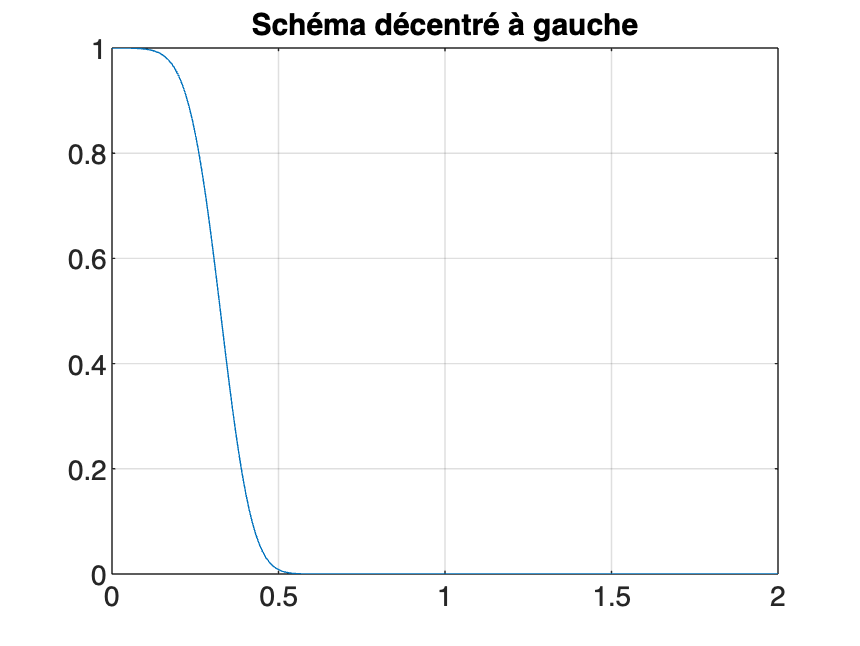

for k=1:Z
    B=(eye(N)+(deltat/deltax)*(1+sin(alpha*k*deltat))*Agauche);
    Ugauche=B*Ugauche;
    plot(X,Ugauche);
    pause(0.01);
    grid on
    title(['Schéma décentré à gauche'])
end

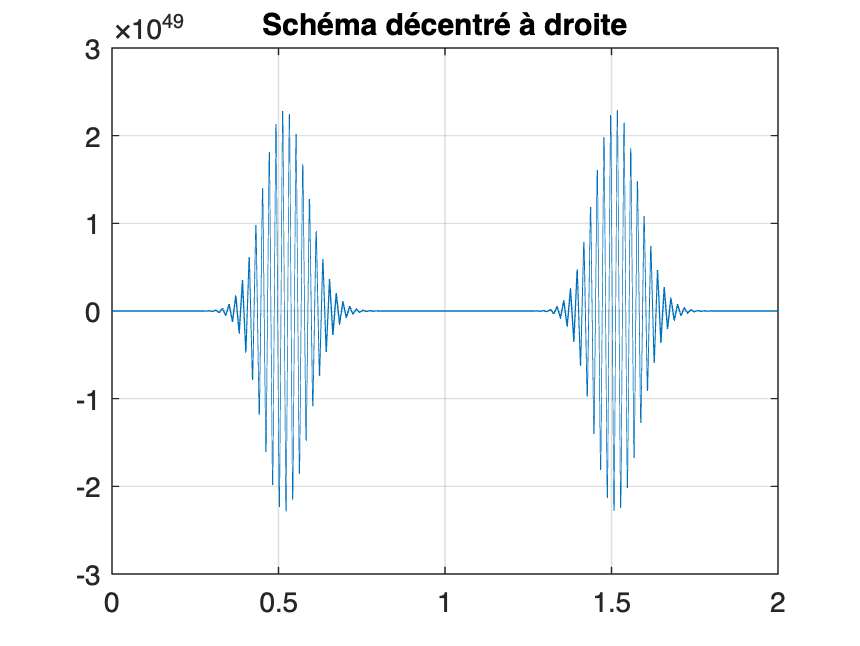

for k=1:Z
    B=(eye(N)+(deltat/deltax)*(1+sin(alpha*k*deltat))*Adroite);
    Udroite=B*Udroite;
    plot(X,Udroite);
    pause(0.003);
    grid on
    title(['Schéma décentré à droite'])
end

On remarque que la courbe qui correspond à un décentrement à gauche est stable.